# FIR filter results

## Model input

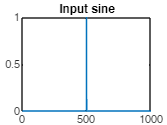

t = 0:1000;
t = t(:);
input = t==500;
% plot(abs(fftshift(fft(input))))
% t = 0:0.001:10;
% t = t(:)
% f = 1;
% input = sin(2*pi*f*t);

plot(input)
title("Input sine")


signed = 1;
word_len = 16;
frac_len = 15;
T = numerictype(signed, word_len, frac_len);
input_q = fi(input, T);
fid = fopen("data/fir_input.txt", "w");
fprintf(fid, "%s\n", string(input_q.bin));
fclose(fid);

## Simulation results

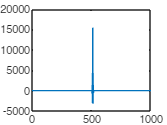

f_out = fopen("data/fir_output.txt", "r");
out = fscanf(f_out, "%f\n");
plot(out)

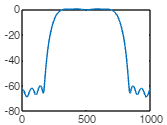

plot(20*log(abs(fftshift(fft(out/(2^15))))))

# Adaptive filter results

## Input

ns = 10000;
fs = 48e3;
f = 5e3;
t = 0:1/fs:(ns-1)/fs;
t = t(:);
input = 0.5*sin(2*pi*f*t);
desired = 0.5*cos(2*pi*f*t);

signed = 1;
word_len = 16;
frac_len = 12;
T = numerictype(signed, word_len, frac_len);

input_q = fi(input, T);
fid = fopen("data/adaptive_filter_input.txt", "w");
fprintf(fid, "%s\n", string(input_q.bin));
fclose(fid);

desired_q = fi(desired, T);
fid = fopen("data/adaptive_filter_desired.txt", "w");
fprintf(fid, "%s\n", string(desired_q.bin));
fclose(fid);

## Model results

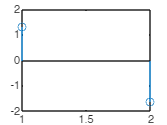

lms = dsp.LMSFilter('Method', 'LMS', 'Length', 2, 'StepSize', 0.1);
[y,e,w] = lms(input, desired);
stem(w)


% plot(e);
% plot(y);
% plot(20*log(abs(fftshift(fft(y)))))
% [mse, meanw, w, ~] = msesim(lms, input, desired);
% w
% plot(mse)
% title("Model MSE")

## Simulation results

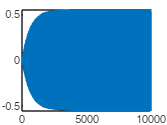

f_out = fopen("data/output.txt", "r");
out = fscanf(f_out, "%d\n");
plot(out/2^12)

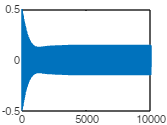

% plot(20*log(abs(fftshift(fft(out/(2^15))))))

f_err = fopen("data/error.txt", "r");
error = fscanf(f_err, "%d\n");
plot(error/2^12)